% Simon Yoon
% ECE300PS04Q2

clear;
clc;
close all;


## Part A

fprintf("\nPart A\n");


Part A


syms F_c F_s; 
fc = 10; %carrier freq
Fc = F_c;
disp(Fc);

$$F_{c}$$

fprintf(" = %d", fc);

 = 10

fs = 100; %sampling rate
Fs = F_s;
disp(Fs);

$$F_{s}$$

fprintf(" = %d", fs);

 = 100

N = 4096;
dt = 1/fs;
n = 0:2000; 
t = n*dt; %time vector
fprintf("N = %d", N);

N = 4096


m = 1 ./ (1 + (t-10).^2); 
mhat = (t-10) ./ (1 +(t-10).^2); 

## Part B

k = (-N/2):(N/2-1);    
f = k*fs/N;

## Part C

fprintf("\nPart C\n");


Part C


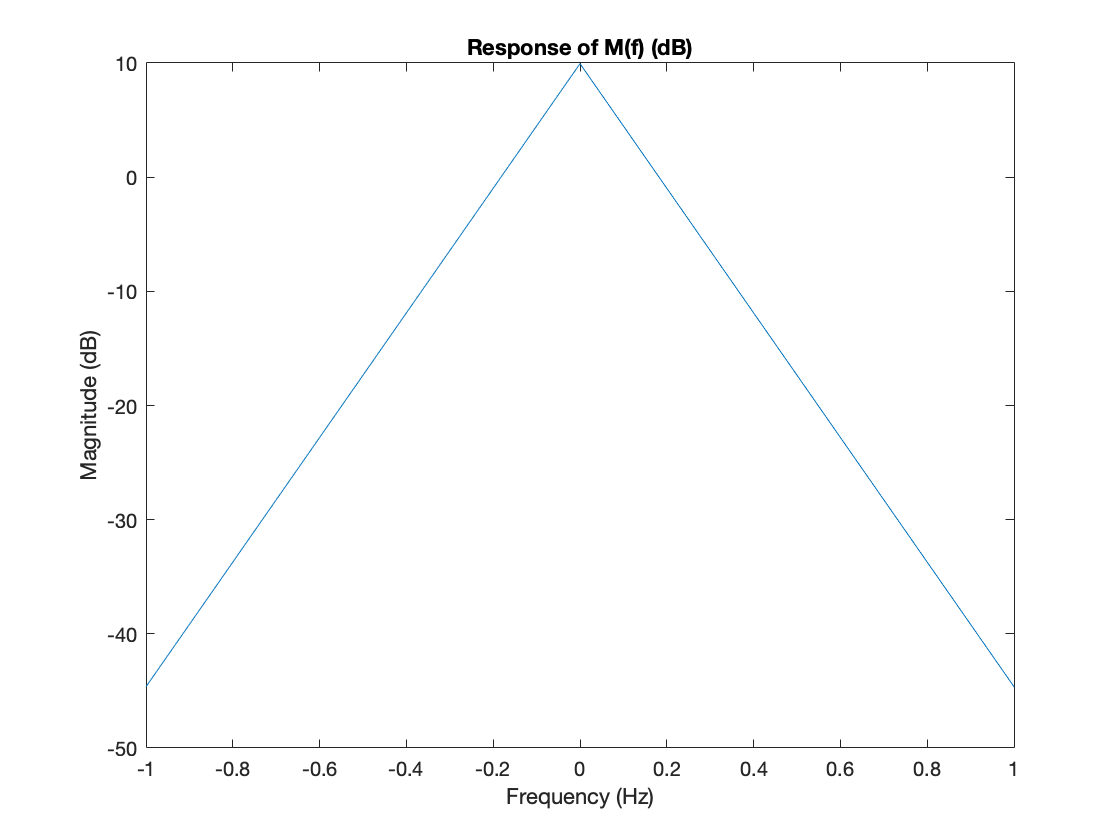

M = pi.*exp(-1j.*40.*pi.*f).*exp(-2.*pi.*abs(f));
abs_M = 20*log10(abs(M));

figure(1)
plot(f, abs_M);
xlim([-1 1])
title("Response of M(f) (dB)")
ylabel("Magnitude (dB)")
xlabel("Frequency (Hz)")

## Part D

fprintf("\nPart D\n");


Part D


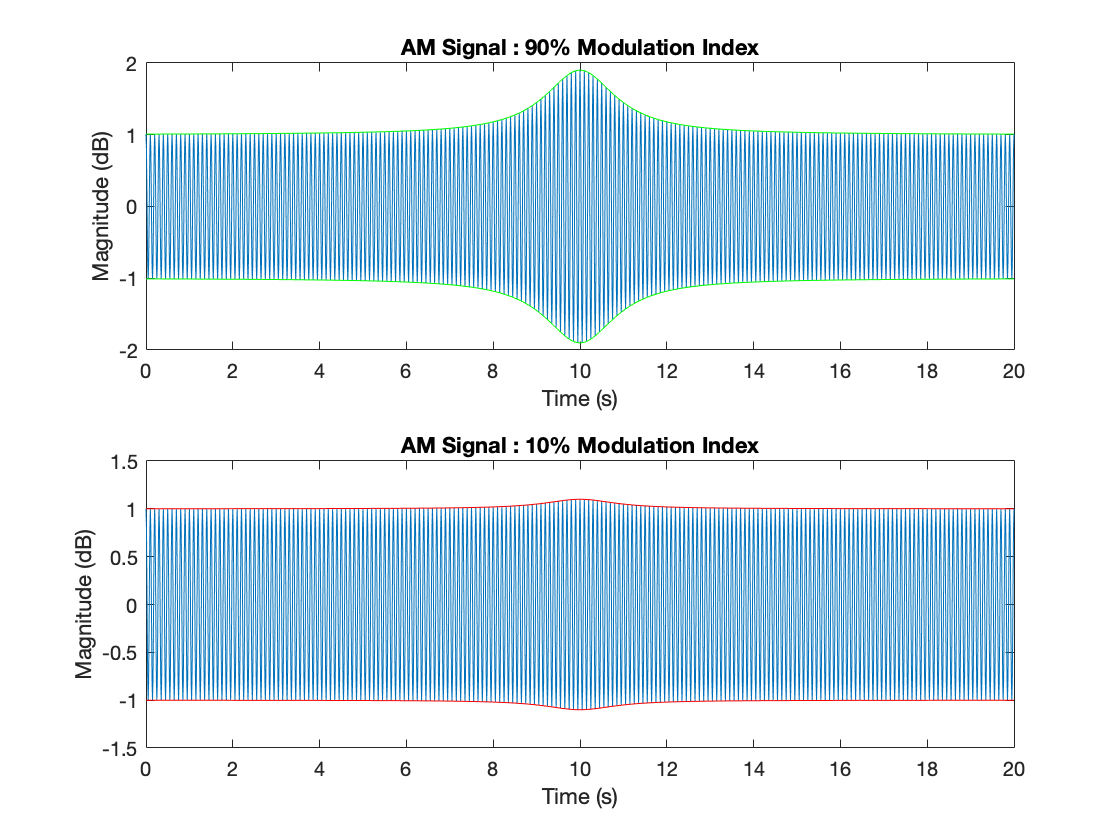

figure(2)
subplot(2,1,1);
xAM_90 = (1 +.9.*m).*cos(2.*pi.*fc.*t);
envAM_90 = 1+.9.*m;
plot(t, xAM_90, t, envAM_90, 'green', t, -envAM_90, 'green')
title("AM Signal : 90% Modulation Index")
ylabel("Magnitude (dB)")
xlabel("Time (s)")

subplot(2,1,2);
xAM_10 = (1 +.1.*m).*cos(2.*pi.*fc.*t);
envAM_10 = 1 +.1.*m;
plot(t, xAM_10, t, envAM_10, 'red', t, -envAM_10, 'red')
title("AM Signal : 10% Modulation Index")
ylabel("Magnitude (dB)")
xlabel("Time (s)")

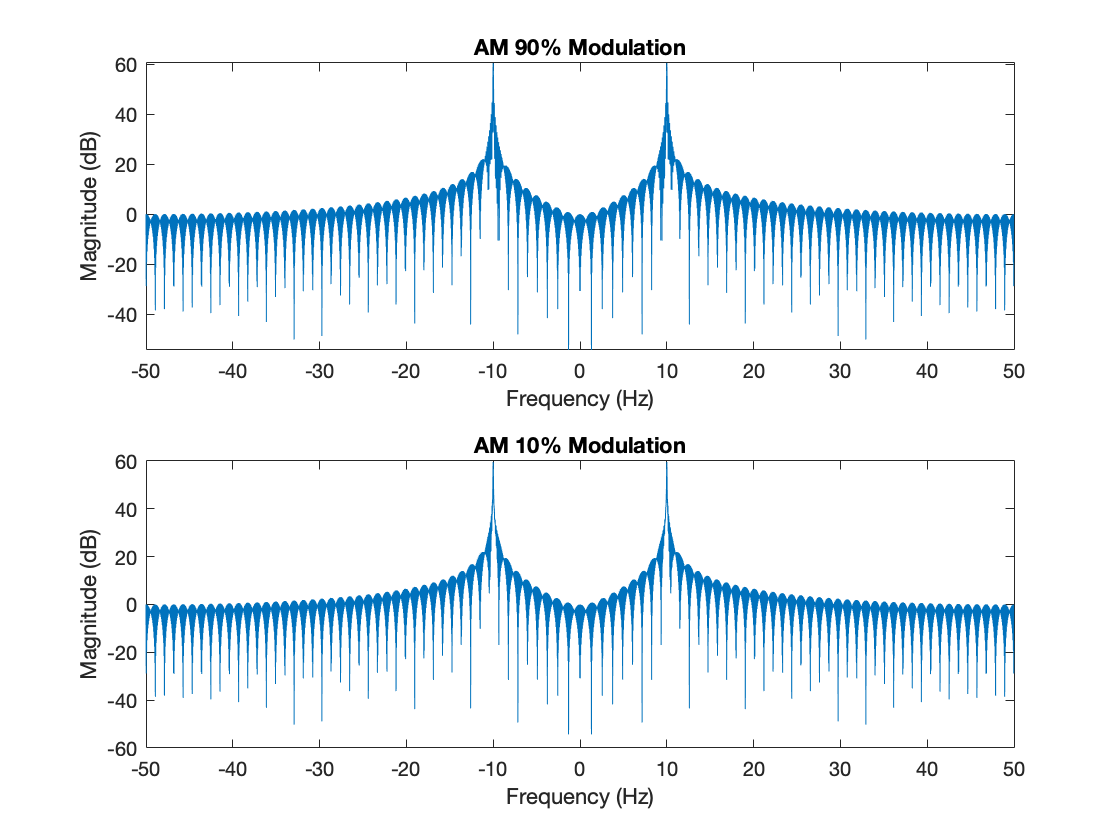


figure(3)
subplot(2,1,1);
xAM_90f = fft(xAM_90, 4096);
xAM_90f = fftshift(xAM_90f);
xAM_90fDB = 20*log10(abs(xAM_90f));
plot(f, xAM_90fDB)
title("AM 90% Modulation")
ylabel("Magnitude (dB)")
xlabel("Frequency (Hz)")

subplot(2,1,2);
xAM_10f = fft(xAM_10, 4096);
xAM_10f = fftshift(xAM_10f);
xAM_10fDB = 20*log10(abs(xAM_10f));
plot(f, xAM_10fDB)
title("AM 10% Modulation")
ylabel("Magnitude (dB)")
xlabel("Frequency (Hz)")

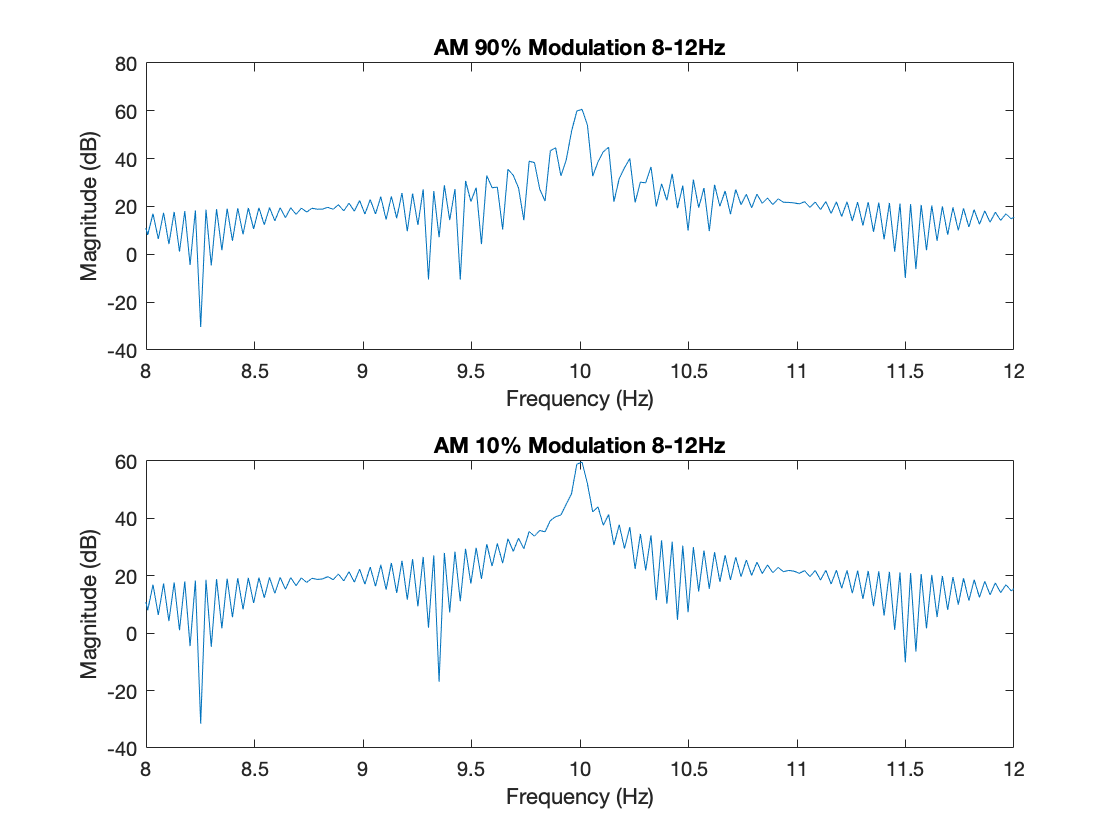


figure(4)
subplot(2,1,1);
plot(f, xAM_90fDB)
xlim([8 12]);
title("AM 90% Modulation 8-12Hz")
ylabel("Magnitude (dB)")
xlabel("Frequency (Hz)")

subplot(2,1,2);
plot(f, xAM_10fDB)
xlim([8 12]);
title("AM 10% Modulation 8-12Hz")
ylabel("Magnitude (dB)")
xlabel("Frequency (Hz)")

## Part E

fprintf("\nPart E\n");


Part E


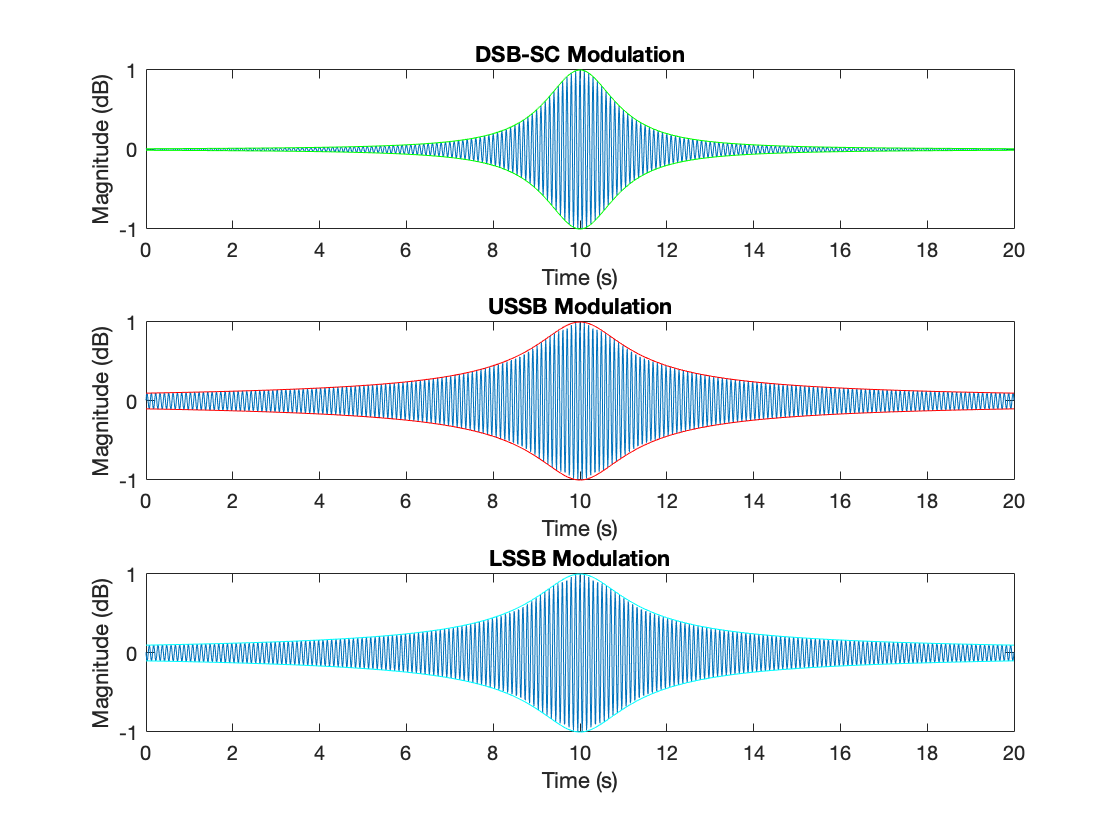

figure(5);
subplot(3,1,1);
DSB_SC = m.*cos(2.*pi.*fc.*t);
env_DSB_SC = m;
plot(t, DSB_SC, t, env_DSB_SC, 'green', t, -env_DSB_SC, 'green');
title("DSB-SC Modulation")
ylabel("Magnitude (dB)")
xlabel("Time (s)")

subplot(3,1,2)
USSB = m.*cos(2.*pi.*fc.*t) - mhat.*sin(2.*pi.*fc.*t);
env_USSB = sqrt(m.^2 + (-mhat).^2);
plot(t, USSB, t, env_USSB, 'red', t, -env_USSB, 'red');
title("USSB Modulation")
ylabel("Magnitude (dB)")
xlabel("Time (s)")

subplot(3,1,3)
LSSB = m.*cos(2.*pi.*fc.*t) + mhat.*sin(2.*pi.*fc.*t);
env_LSSB = sqrt(m.^2 + mhat.^2);
plot(t, LSSB, t, env_LSSB, 'cyan', t, -env_LSSB, 'cyan');
title("LSSB Modulation")
ylabel("Magnitude (dB)")
xlabel("Time (s)")

## Part G

fprintf("\nPart G\n");


Part G


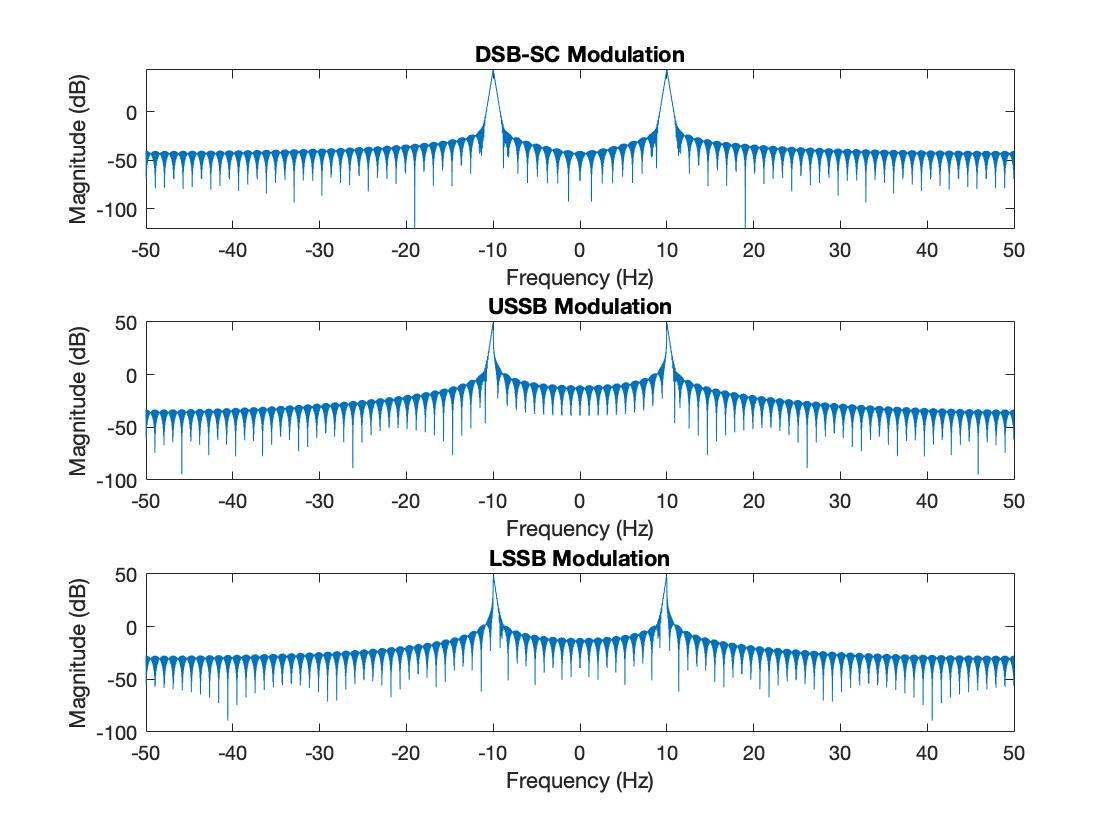

figure(6);
subplot(3,1,1);
DSB_SCf = fft(DSB_SC, 4096);
DSB_SCf = fftshift(DSB_SCf);
DSB_SCf_dB = 20*log10(abs(DSB_SCf));
plot(f, DSB_SCf_dB)
title("DSB-SC Modulation")
ylabel("Magnitude (dB)")
xlabel("Frequency (Hz)")

subplot(3,1,2);
USSBf = fft(USSB, 4096);
USSBf = fftshift(USSBf);
USSBf_dB = 20*log10(abs(USSBf));
plot(f, USSBf_dB)
title("USSB Modulation")
ylabel("Magnitude (dB)")
xlabel("Frequency (Hz)")

subplot(3,1,3);
LSSBf = fft(LSSB, 4096);
LSSBf = fftshift(LSSBf);
LSSBf_dB = 20*log10(abs(LSSBf));
plot(f, LSSBf_dB)
title("LSSB Modulation")
ylabel("Magnitude (dB)")
xlabel("Frequency (Hz)")

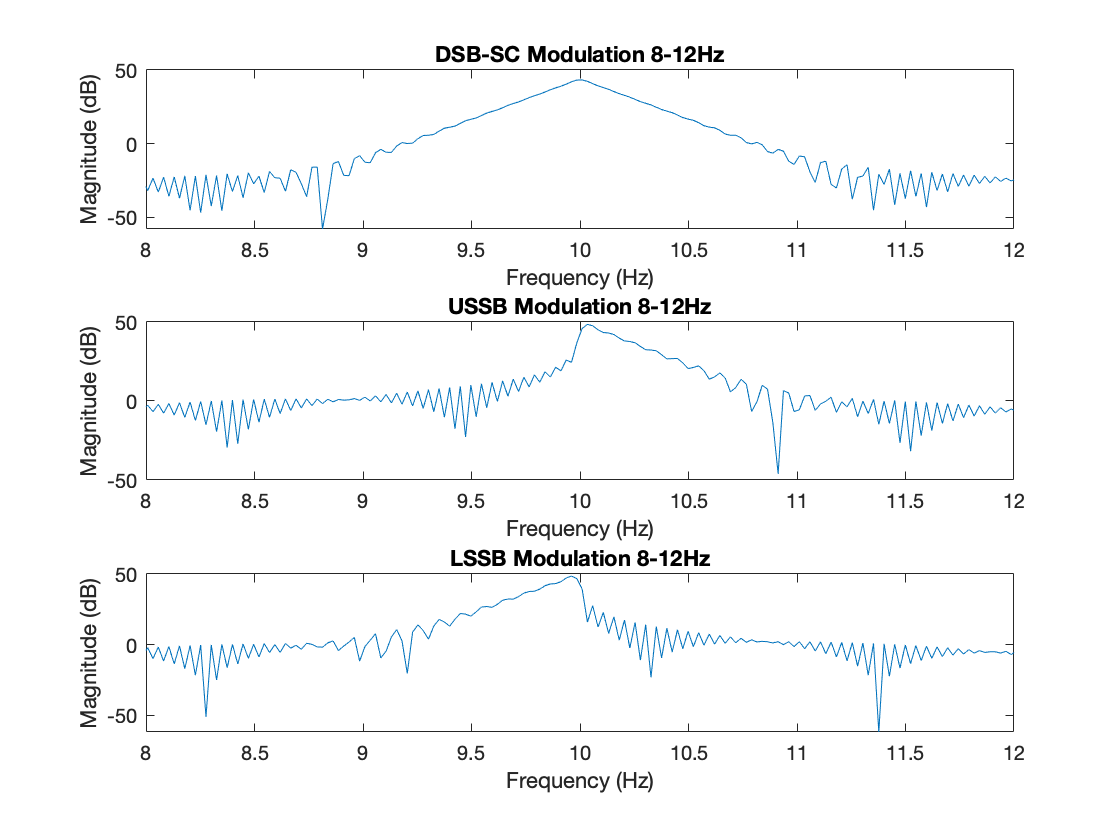


figure(7)
subplot(3,1,1);
plot(f, DSB_SCf_dB);
xlim([8 12]);
title("DSB-SC Modulation 8-12Hz")
ylabel("Magnitude (dB)")
xlabel("Frequency (Hz)")

subplot(3,1,2);
plot(f, USSBf_dB);
xlim([8 12]);
title("USSB Modulation 8-12Hz")
ylabel("Magnitude (dB)")
xlabel("Frequency (Hz)")

subplot(3,1,3);
plot(f, LSSBf_dB);
xlim([8 12]);
title("LSSB Modulation 8-12Hz")
ylabel("Magnitude (dB)")
xlabel("Frequency (Hz)")

## Part H

fprintf("\nPart H\n");


Part H


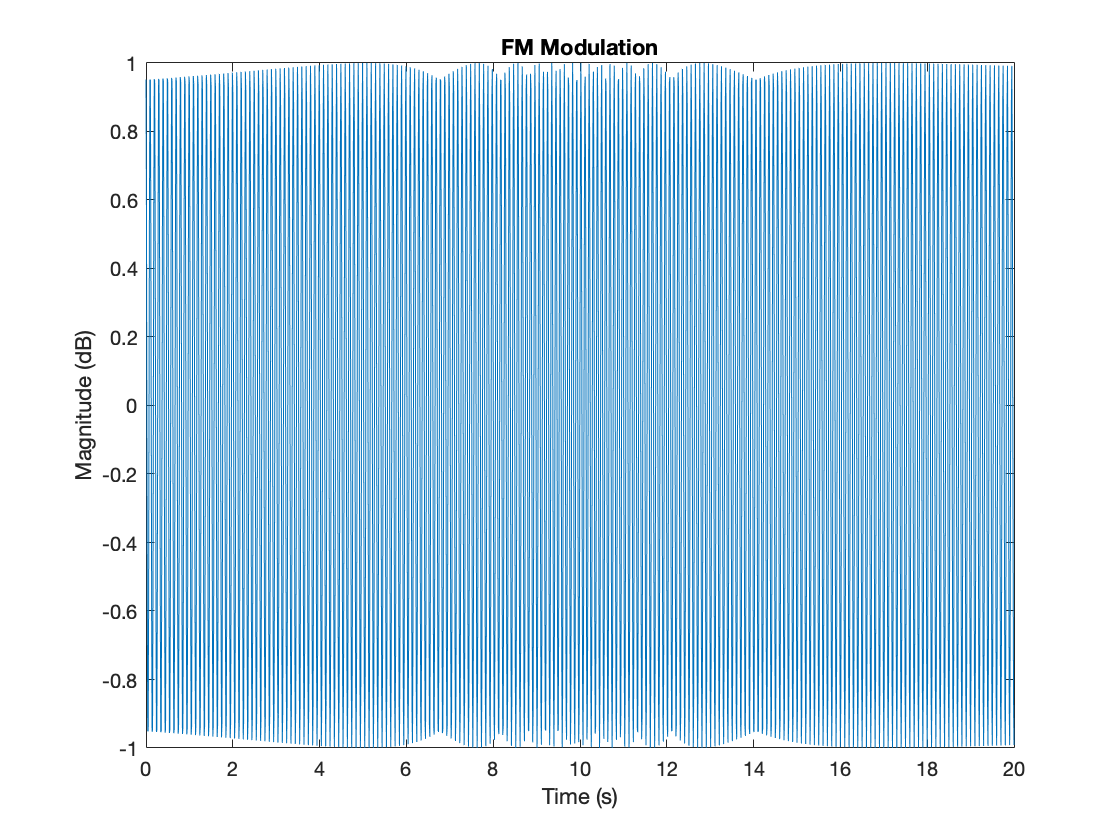

kf = .5;
figure(8)
FM = cos(2.*pi.*fc.*t + 2.*pi.*kf.*((pi/2)+atan(t-10)));
plot(t, FM);
title("FM Modulation")
ylabel("Magnitude (dB)")
xlabel("Time (s)")

## Part I

fprintf("\nPart I\n");


Part I


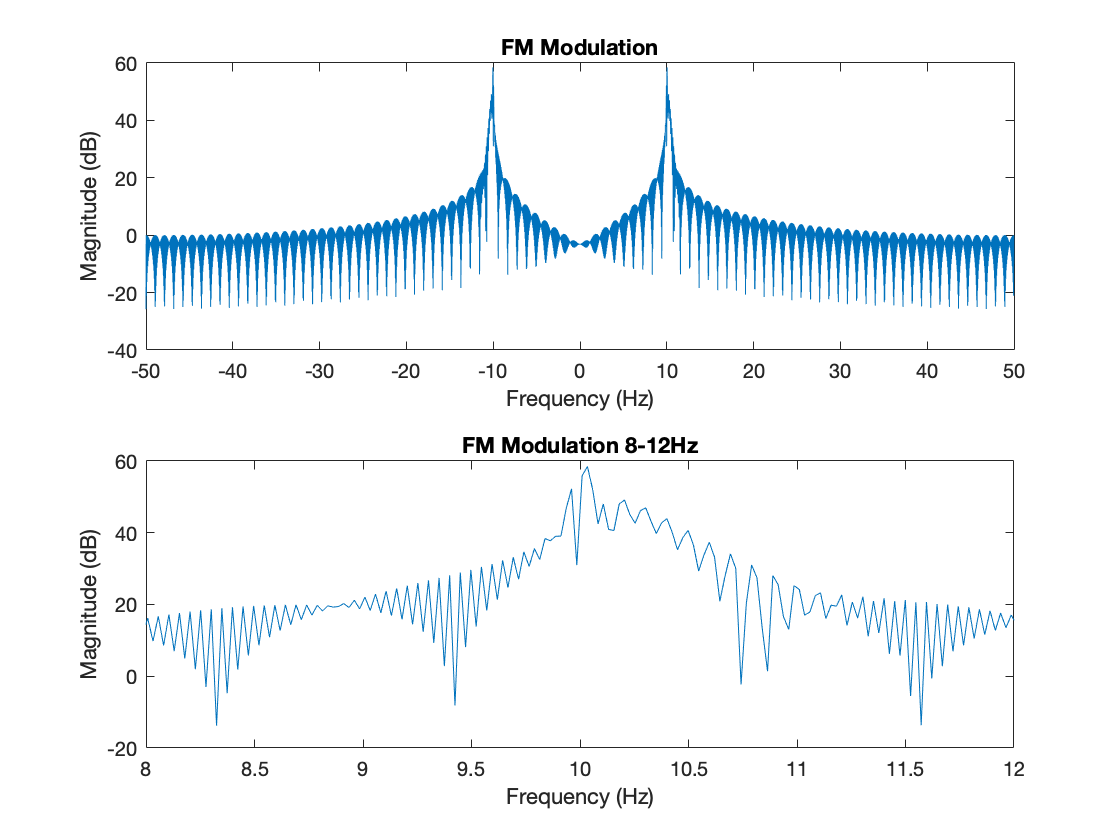

figure(9)
subplot(2,1,1)
FMf = fft(FM, 4096);
FMf = fftshift(FMf);
FMfDB = 20*log10(abs(FMf));
plot(f, FMfDB)
title("FM Modulation")
ylabel("Magnitude (dB)")
xlabel("Frequency (Hz)")

subplot(2,1,2)
plot(f, FMfDB)
xlim([8 12]);
title("FM Modulation 8-12Hz")
ylabel("Magnitude (dB)")
xlabel("Frequency (Hz)")

## Part J

fprintf("\nPart J\n");


Part J


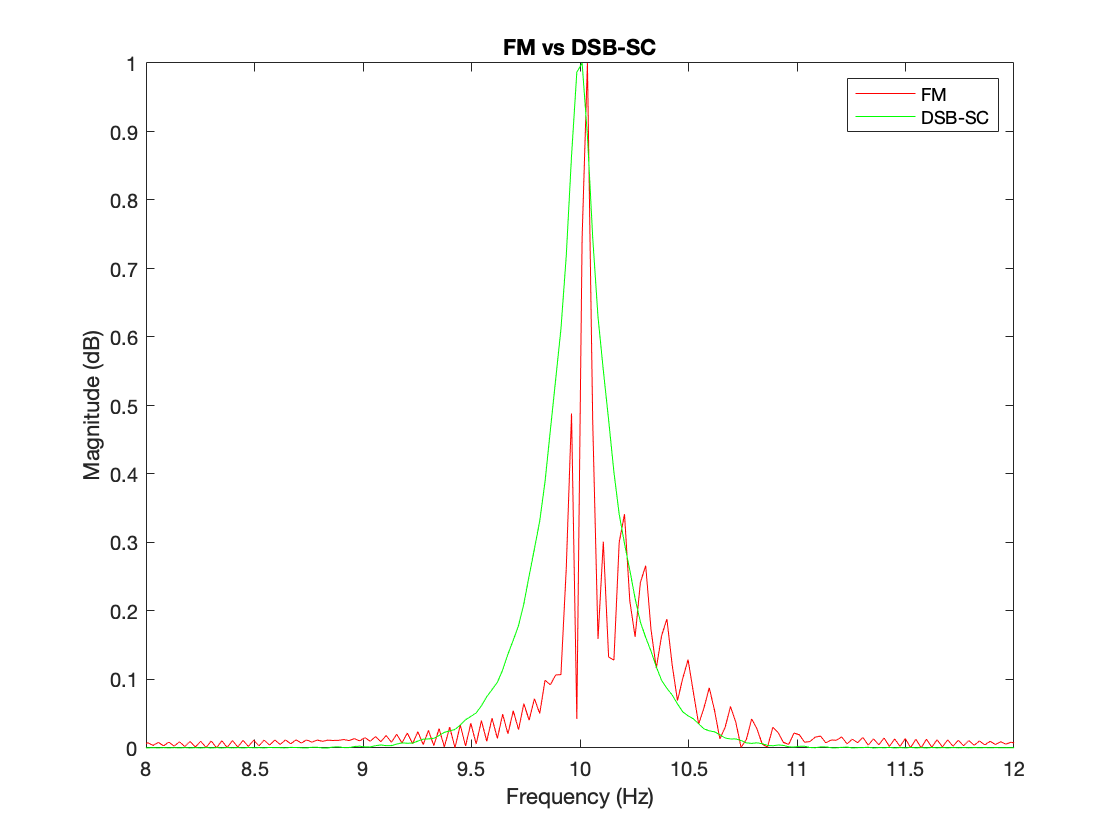

figure(10); 
plot(f, abs(FMf)/max(abs(FMf)) , 'red', f, abs(DSB_SCf)/max(abs(DSB_SCf)), 'green');
legend('FM','DSB-SC')
xlim([8 12]);
title("FM vs DSB-SC")
ylabel("Magnitude (dB)")
xlabel("Frequency (Hz)")